# `Digital Control Systems Final CA`

## Shayan Vassef, 810197603

## Arman Barghi, 810197470

# **Equilibrium point / Transfer function (p1)**

## **Defining Variables**

clear; clc; close all;

syms G X I U D
Gb = 4.5;
Ib = 15;
P1 = 0;
P2 = 0.025;
P3 = 0.000013;
V = 12;
n = 5.54/60;
F = [ -P1*G-X*(G+Gb)+D;
      -P2*X+P3*I;
      -n*(I+Ib)+U/V ];
y = G;

St = [G;X;I];
In = [U;D];

## **Equilibrium State**

St_e = [0;0;0];
In_e = [n*Ib*V;0];
Fe = subs(subs(F,In,In_e),St,St_e);

## Linearize

% f(x) = f(xe,ue) + (grad(f,x)|x=xe,u=ue)*(x-xe) + (grad(f,u)|x=xe,u=ue)*(u-ue)
grad_F_St = [ diff(F(1),St(1)), diff(F(1),St(2)), diff(F(1),St(3));
              diff(F(2),St(1)), diff(F(2),St(2)), diff(F(2),St(3));
              diff(F(3),St(1)), diff(F(3),St(2)), diff(F(3),St(3)) ];
grad_F_In = [ diff(F,In(1)) , diff(F,In(2)) ];
A = double(subs(subs(grad_F_St,In,In_e),St,St_e))

A =          0   -4.5000         0
         0   -0.0250    0.0000
         0         0   -0.0923


B = double(subs(subs(grad_F_In,In,In_e),St,St_e));
B = B(:,1)

B =          0
         0
    0.0833


C = [1,0,0]

C =      1     0     0


D = 0

D = 0

## Transfer Function

syms s
n = size(A,1);
Gp = C*inv(s*eye(n)-A)*B;
ExpFun = matlabFunction(simplifyFraction(Gp,'Expand',true));
ExpFun = str2func(regexprep(func2str(ExpFun), '\.([/^\\*])', '$1'));
Gp = tf(ExpFun(tf('s')));
for i = 1:length(Gp)
    [num,den] = tfdata(Gp(i));
    Gp(i) = tf(num{1}/den{1}(1),den{1}/den{1}(1));
end
Gp = Gp(1)

Gp =
 
           -4.875e-06
  -----------------------------
  s^3 + 0.1173 s^2 + 0.002308 s
 
Continuous-time transfer function.



[Gp_Num, Gp_Den] = tfdata(Gp); Gp_Num = Gp_Num{1}; Gp_Den = Gp_Den{1};

# **Analog Control (p2)**

%pidTuner

Gc = tf([-7.83 -0.001947],[1 0])

Gc =
 
  -7.83 s - 0.001947
  ------------------
          s
 
Continuous-time transfer function.



trans_info = stepinfo(feedback(series(Gc,Gp),1))

trans_info = struct with fields:
        RiseTime: 83.7907
    SettlingTime: 312.4786
     SettlingMin: 0.9142
     SettlingMax: 1.1813
       Overshoot: 18.1258
      Undershoot: 0
            Peak: 1.1813
        PeakTime: 194.7882


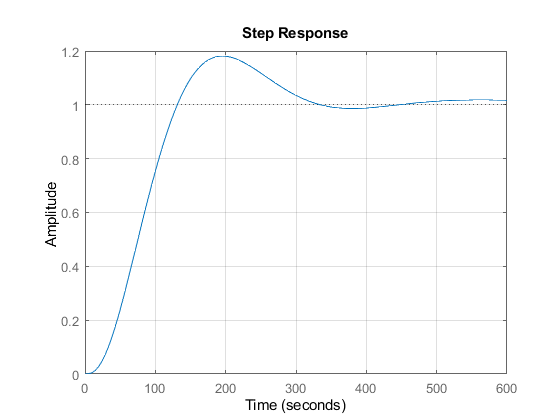

step(feedback(series(Gc,Gp),1))
grid on

[Gc_Num, Gc_Den] = tfdata(Gc); Gc_Num = Gc_Num{1}; Gc_Den = Gc_Den{1};

# **Digital Control (P3)**

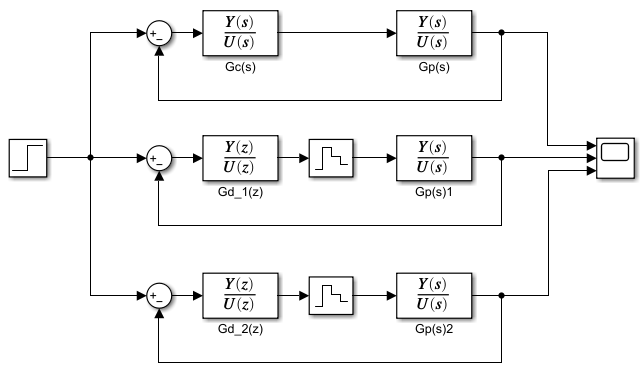

% 2 < tr/Ts < 10
Ts = round(trans_info.RiseTime/6)

Ts = 14

Gd_1 = c2d(Gc,Ts,'tastin')

Gd_1 =
 
  -7.844 z + 7.816
  ----------------
       z - 1
 
Sample time: 14 seconds
Discrete-time transfer function.



Gd_2 = c2d(Gc,Ts,'matched')

Gd_2 =
 
  -7.844 z + 7.816
  ----------------
       z - 1
 
Sample time: 14 seconds
Discrete-time transfer function.



[Gd_Num_1, Gd_Den_1] = tfdata(Gd_1); Gd_Num_1 = Gd_Num_1{1}; Gd_Den_1 = Gd_Den_1{1};
[Gd_Num_2, Gd_Den_2] = tfdata(Gd_2); Gd_Num_2 = Gd_Num_2{1}; Gd_Den_2 = Gd_Den_2{1};

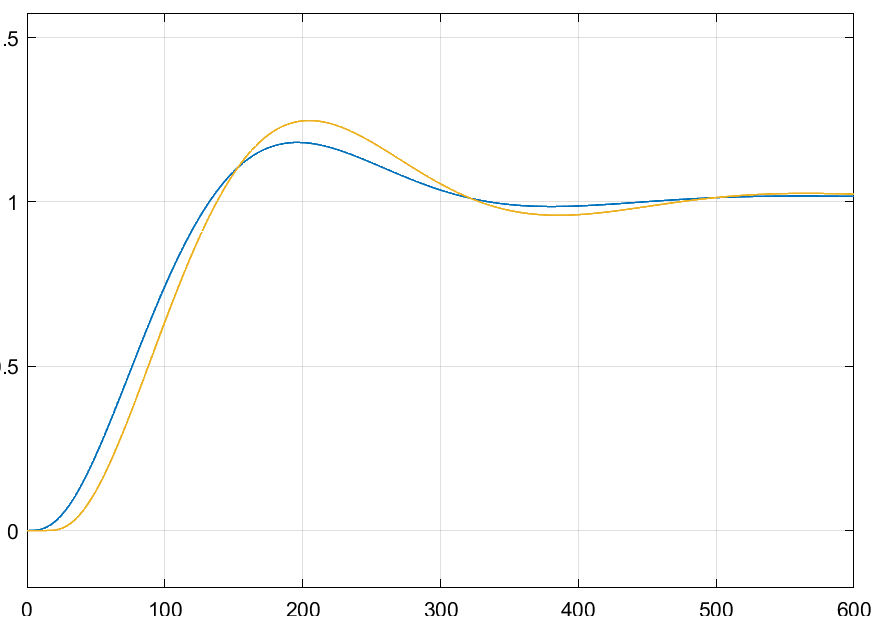

Ts = 4;
Gd_1 = c2d(Gc,Ts,'tastin')

Gd_1 =
 
  -7.834 z + 7.826
  ----------------
       z - 1
 
Sample time: 4 seconds
Discrete-time transfer function.



Gd_2 = c2d(Gc,Ts,'matched')

Gd_2 =
 
  -7.834 z + 7.826
  ----------------
       z - 1
 
Sample time: 4 seconds
Discrete-time transfer function.



[Gd_Num_1, Gd_Den_1] = tfdata(Gd_1); Gd_Num_1 = Gd_Num_1{1}; Gd_Den_1 = Gd_Den_1{1};
[Gd_Num_2, Gd_Den_2] = tfdata(Gd_2); Gd_Num_2 = Gd_Num_2{1}; Gd_Den_2 = Gd_Den_2{1};

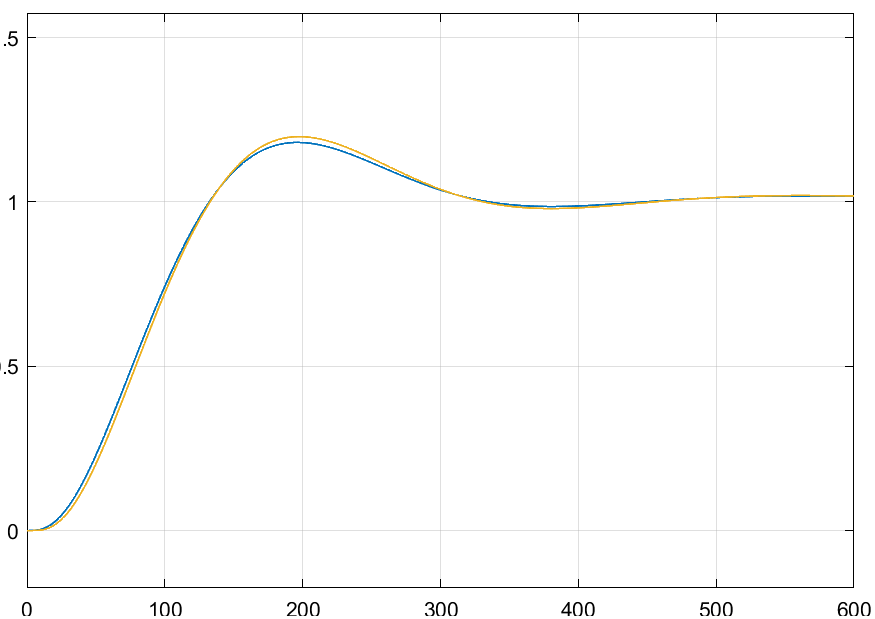

Ts = 40;
Gd_1 = c2d(Gc,Ts,'tastin')

Gd_1 =
 
  -7.869 z + 7.791
  ----------------
       z - 1
 
Sample time: 40 seconds
Discrete-time transfer function.



Gd_2 = c2d(Gc,Ts,'matched')

Gd_2 =
 
  -7.869 z + 7.791
  ----------------
       z - 1
 
Sample time: 40 seconds
Discrete-time transfer function.



[Gd_Num_1, Gd_Den_1] = tfdata(Gd_1); Gd_Num_1 = Gd_Num_1{1}; Gd_Den_1 = Gd_Den_1{1};
[Gd_Num_2, Gd_Den_2] = tfdata(Gd_2); Gd_Num_2 = Gd_Num_2{1}; Gd_Den_2 = Gd_Den_2{1};

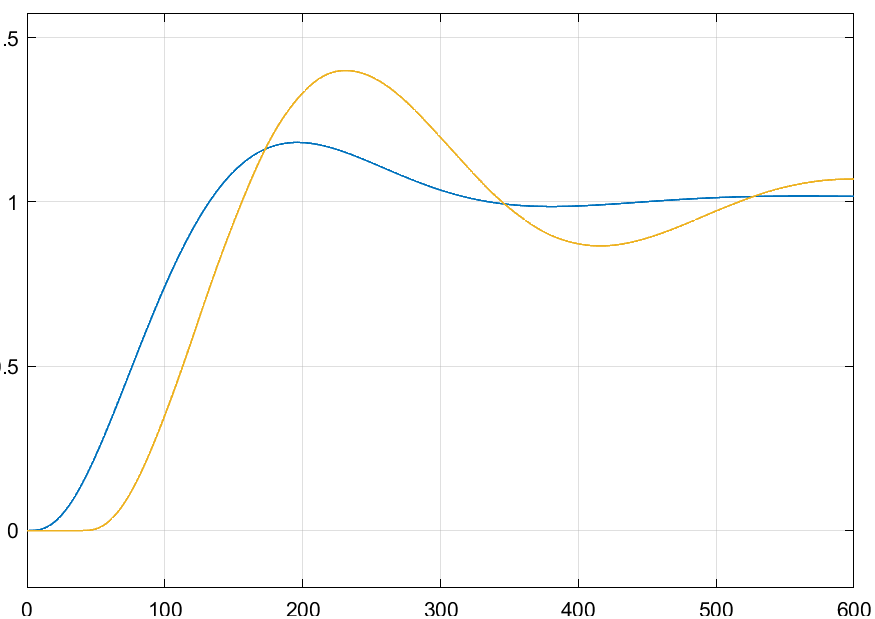

# **Discrete Transfer Function (p4)**

## **Using c2d in matlab :**

Ts = 4;
Gp_d = c2d(Gp,Ts,'zoh')

Gp_d =
 
  -4.635e-05 z^2 - 0.0001652 z - 3.666e-05
  ----------------------------------------
     z^3 - 2.596 z^2 + 2.221 z - 0.6254
 
Sample time: 4 seconds
Discrete-time transfer function.



## Root Locus

For Positive k :

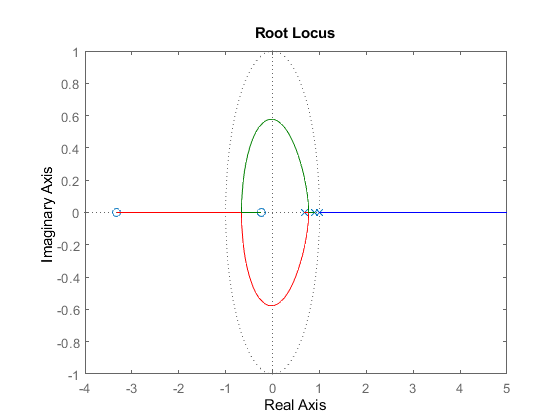

rlocus(Gp_d)

For Negative k :

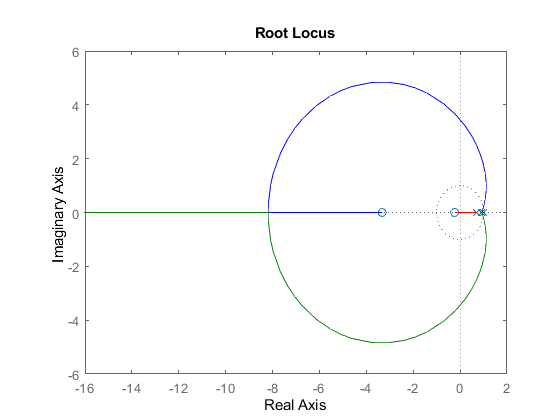

rlocus(-Gp_d)

Deciding the Stable Threshold :

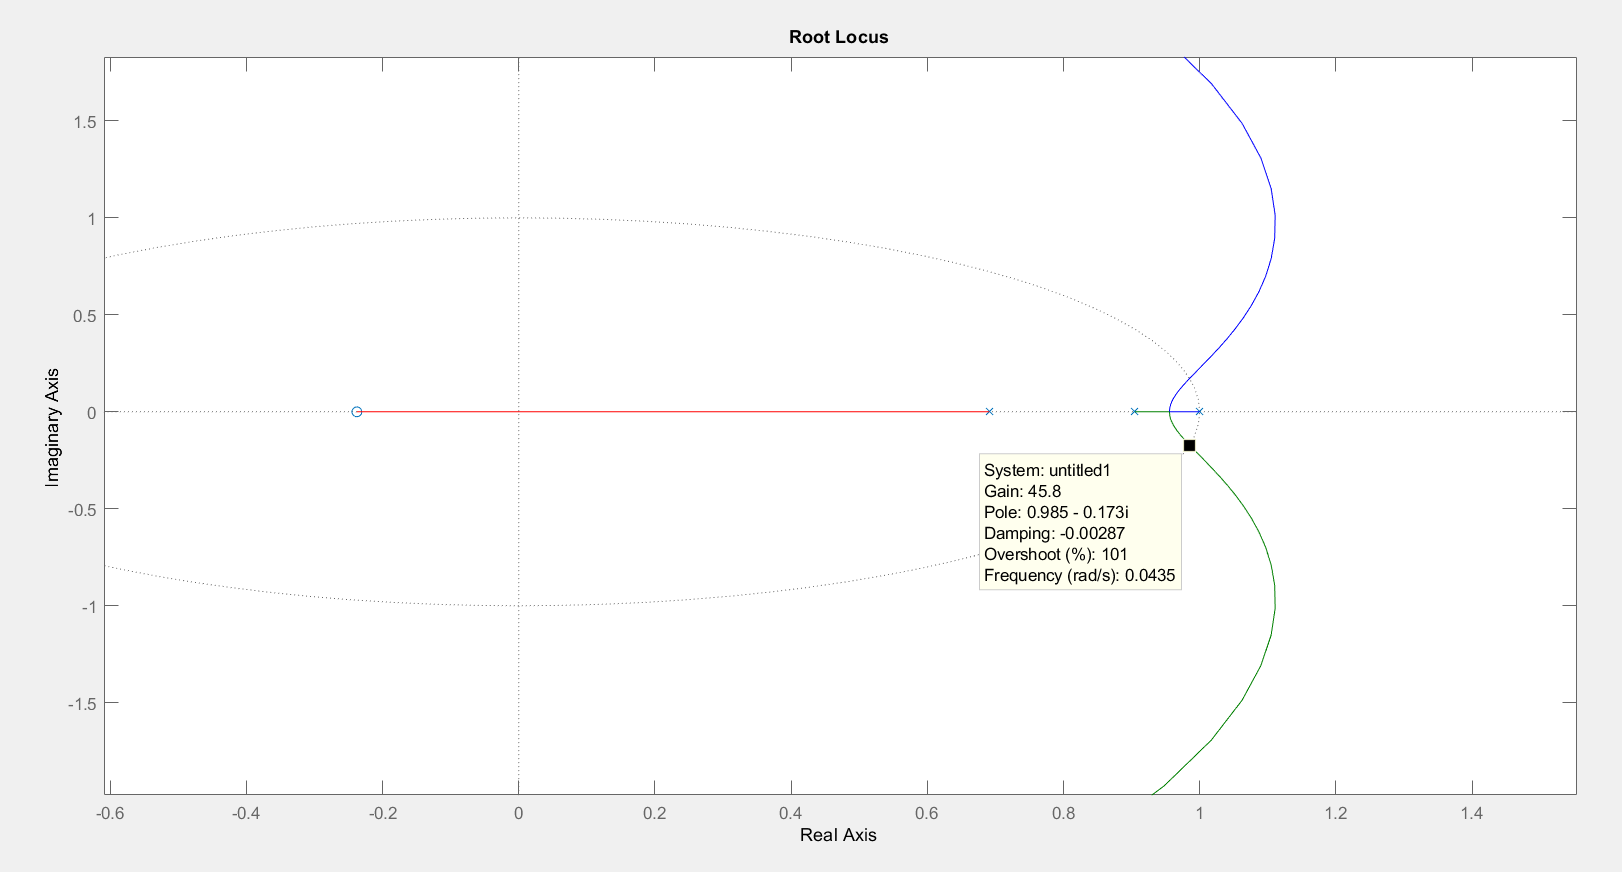

`Therefore => -45.8<k<0`

## `Bode plot `

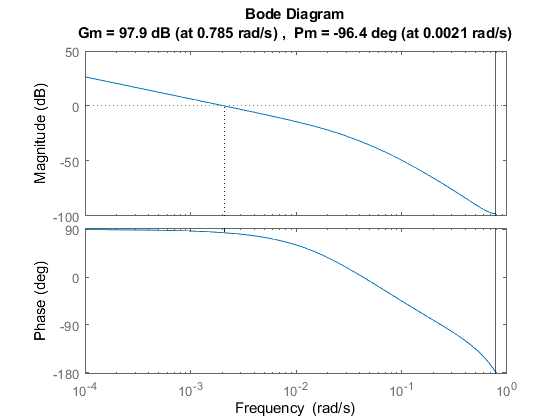

margin(Gp_d)

[Gm,Pm,Wgm,Wpm] = margin(Gp_d)

Gm = 7.8339e+04

Pm = -96.3569

Wgm = 0.7854

Wpm = 0.0021

# **Design a controler (p5)**

Deciding The two major closed loop poles by the given information :

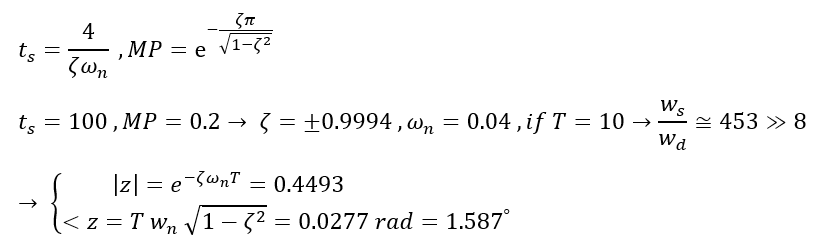

Ts = 10;
Gp_d = c2d(Gp,Ts,'zoh')

Gp_d =
 
  -0.0006143 z^2 - 0.00186 z - 0.000342
  -------------------------------------
   z^3 - 2.176 z^2 + 1.485 z - 0.3093
 
Sample time: 10 seconds
Discrete-time transfer function.



[num,den]=tfdata(Gp_d);

Calculate The zeros, Poles and the Gain of the Discrete Transfer Function :

[z,p,k] = tf2zp(num{1},den{1})

z =    -2.8306
   -0.1967


p =     1.0000
    0.7788
    0.3972


k = -6.1431e-04

Designing a Lead/Lag Controller depending on the position of zeros and poles :

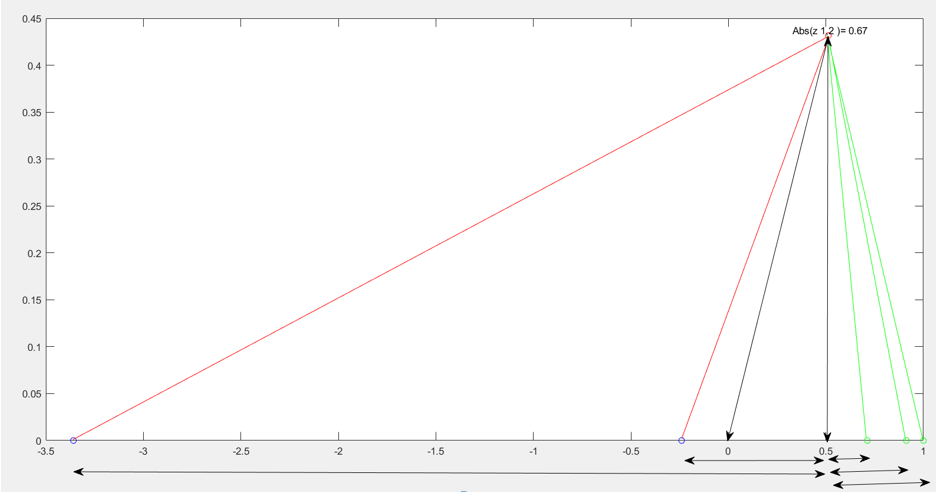

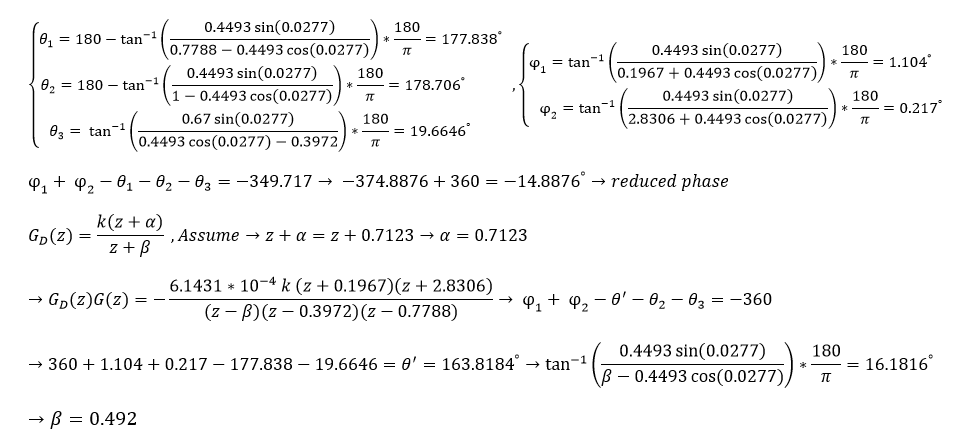

So, Reconstructing the Open loop Transfer function without the coefficient k : Gp(z)*G(z) 

Gop_pre = tf(-6.1431*10^-4*conv([1 0.1967],[1 2.8306]),conv(conv([1,-0.492],[1,-0.3972]), [1,-0.7788]),Ts)

Gop_pre =
 
  -0.0006143 z^2 - 0.00186 z - 0.000342
  -------------------------------------
   z^3 - 1.668 z^2 + 0.8879 z - 0.1522
 
Sample time: 10 seconds
Discrete-time transfer function.



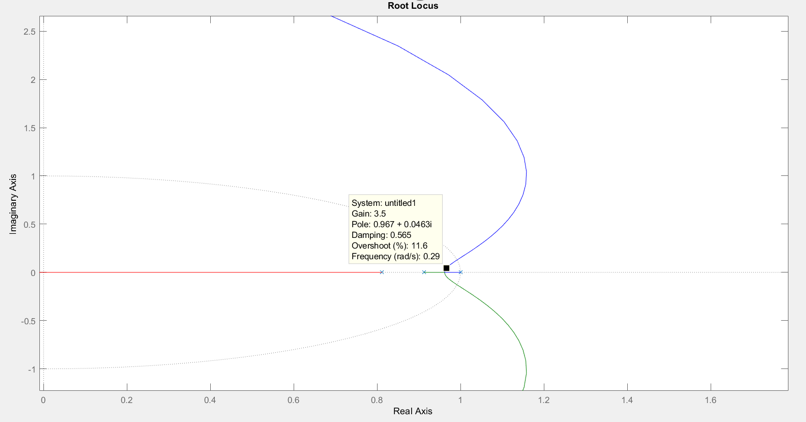

Decide to choose the controller coeffient form root locus

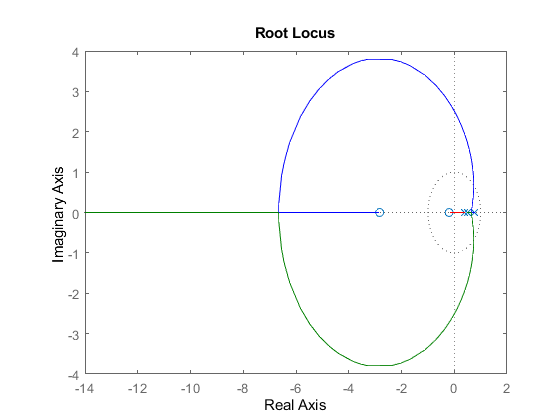

rlocus(-Gop_pre)

choosing k = -3.5, then plot the step response 

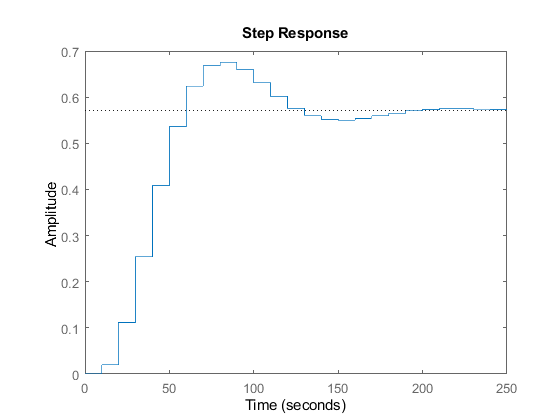

step(feedback(-32*Gop_pre,1))

stepinfo(step(feedback(-32*Gop_pre,1)))

ans = struct with fields:
        RiseTime: 3.4343
    SettlingTime: 18.5526
     SettlingMin: 0.5367
     SettlingMax: 0.6758
       Overshoot: 17.6908
      Undershoot: 0
            Peak: 0.6758
        PeakTime: 9


Gop = -32*Gop_pre

Gop =
 
   0.01966 z^2 + 0.05951 z + 0.01095
  -----------------------------------
  z^3 - 1.668 z^2 + 0.8879 z - 0.1522
 
Sample time: 10 seconds
Discrete-time transfer function.



# **Comparing the features per plot (p6)**

## Bode plot ( Uncontrolled system )

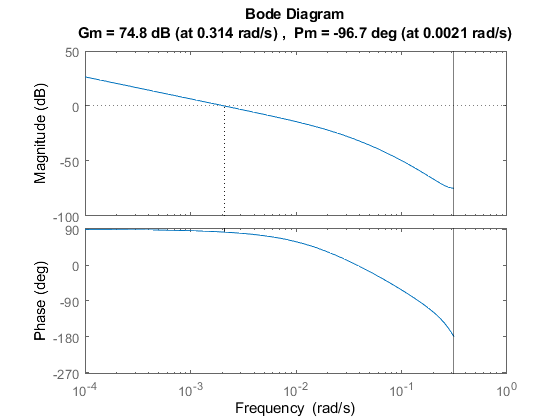

margin(Gp_d)

[Gm,Pm,Wgm,Wpm] = margin(Gp_d)

Gm = 5.5026e+03

Pm = -96.7192

Wgm = 0.3142

Wpm = 0.0021

BW_us = bandwidth(Gp_d)

BW_us = Inf

So the obtaind Bandwidth for the uncontrolled system is infinity, meaning there is no threshold found that we have a significant gain(This is due to the fact that the bode plot is strictly decreasing from the very first).

## Bode Plot (Controlled system)

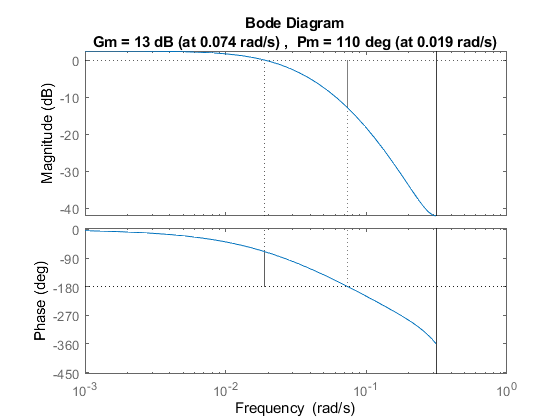

margin(Gop)

[Gm,Pm,Wgm,Wpm] = margin(Gop)

Gm = 4.4548

Pm = 110.0369

Wgm = 0.0740

Wpm = 0.0190

BW_cs = bandwidth(Gop)

BW_cs = 0.0214

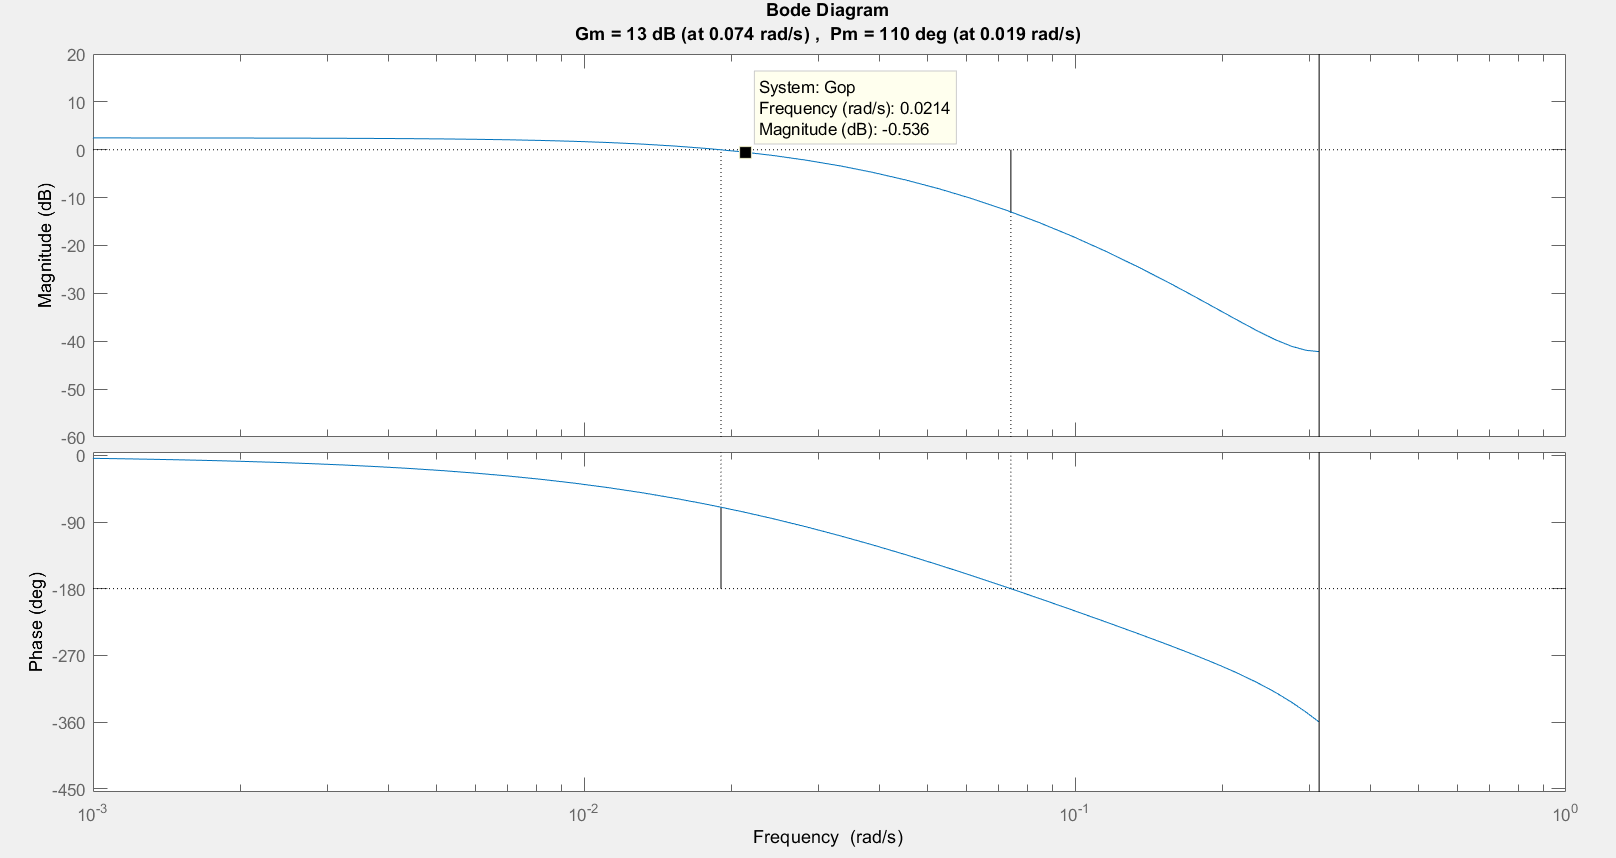

As you can see, The result obtained from the bandwidth function and calculated bandwidth from the bode plot (-3db fall ) are approximatly the same.

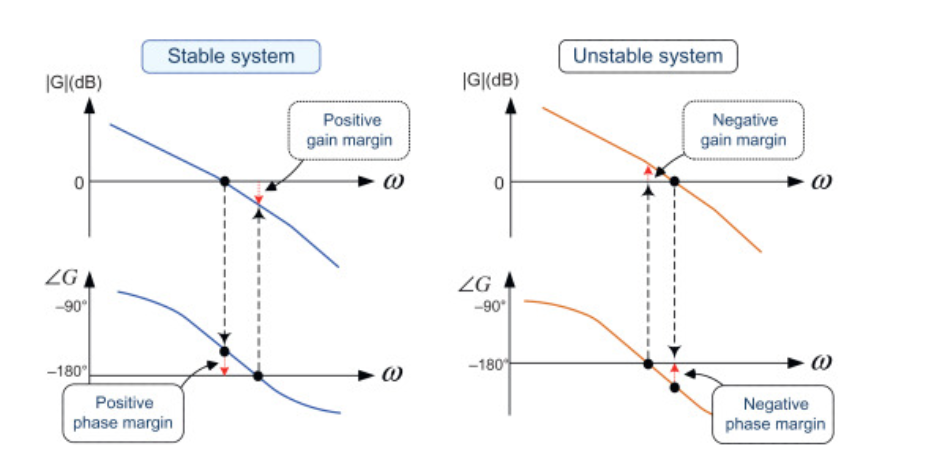

**Gain margin** is defined as the amount of change in open-loop gain needed to make a closed-loop system unstable. The gain margin is the difference between 0 dB and the gain at the phase cross-over frequency that gives a phase of −180°. If the gain |GH(jω)| at the frequency of ∠GH(jω)=−180° is greater than 0 dB as shown in the left above figure, meaning a positive gain margin, then the closed-loop system is stable.

**Phase margin** is defined as the amount of change in open-loop phase needed to make a closed-loop system unstable. The phase margin is the difference in phase between −180° and the phase at the gain cross-over frequency that gives a gain of 0 dB. If the phase ∠GH(jω) at the frequency of |GH(jω)|=1 is greater than −180° as shown in the above left figure, meaning a positive phase margin, the closed-loop system is stable.

If a closed-loop system is stable, both the gain margin and the phase margin need to be positive. So as we can see from the above bode plots, the uncontrolled system has a negative phase margin, so it is unstable and the controlled system has the positive phase and gain margin which is why it is stable. In general, the phase margin of 30–60 degrees and the gain margin of 2–10 dB are desirable in the closed-loop system design. A system with a large gain margin and phase margin is stable but has a sluggish response(Means slow to respond), while the one with a small gain margin and phase margin has a less sluggish response but is oscillatory(It has ups and downs).

## Root Locus (Uncontrolled system)

Ts = 10;
Gp_d = c2d(Gp,Ts,'zoh')

Gp_d =
 
  -0.0006143 z^2 - 0.00186 z - 0.000342
  -------------------------------------
   z^3 - 2.176 z^2 + 1.485 z - 0.3093
 
Sample time: 10 seconds
Discrete-time transfer function.



For Positive k :

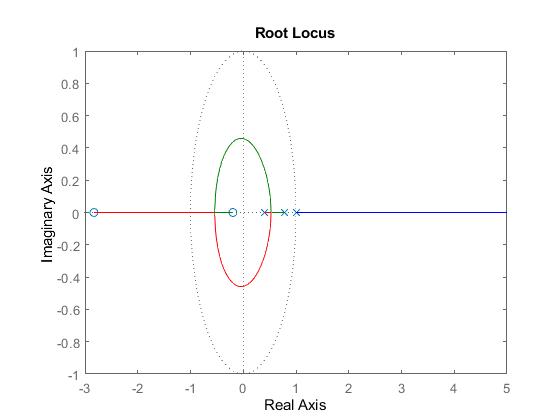

rlocus(Gp_d)

For Negative k :

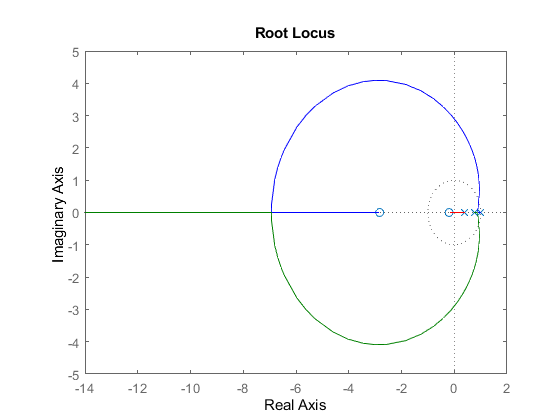

rlocus(-Gp_d)

## Root Locus (Controlled system)

For positive k :

rlocus(Gop)

For negative k :

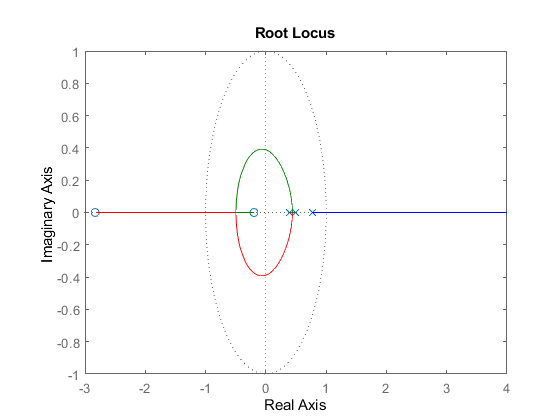

rlocus(-Gop)

# **DeadBeat controller (p7)**

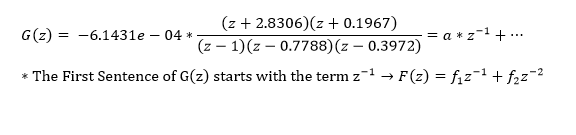

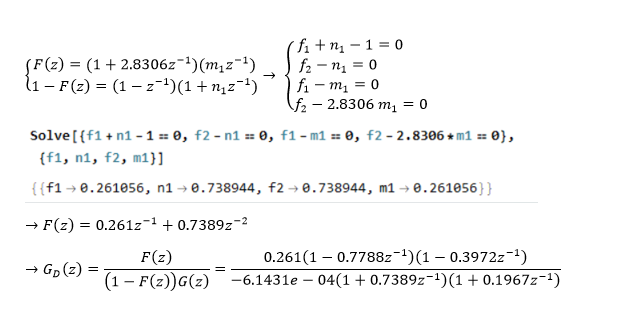

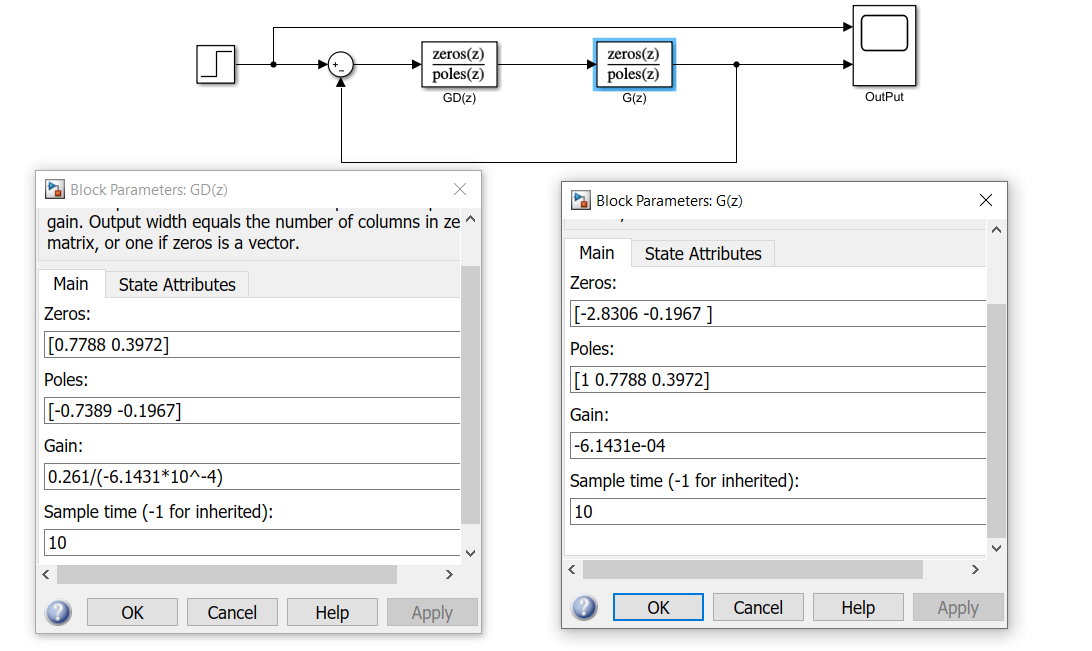

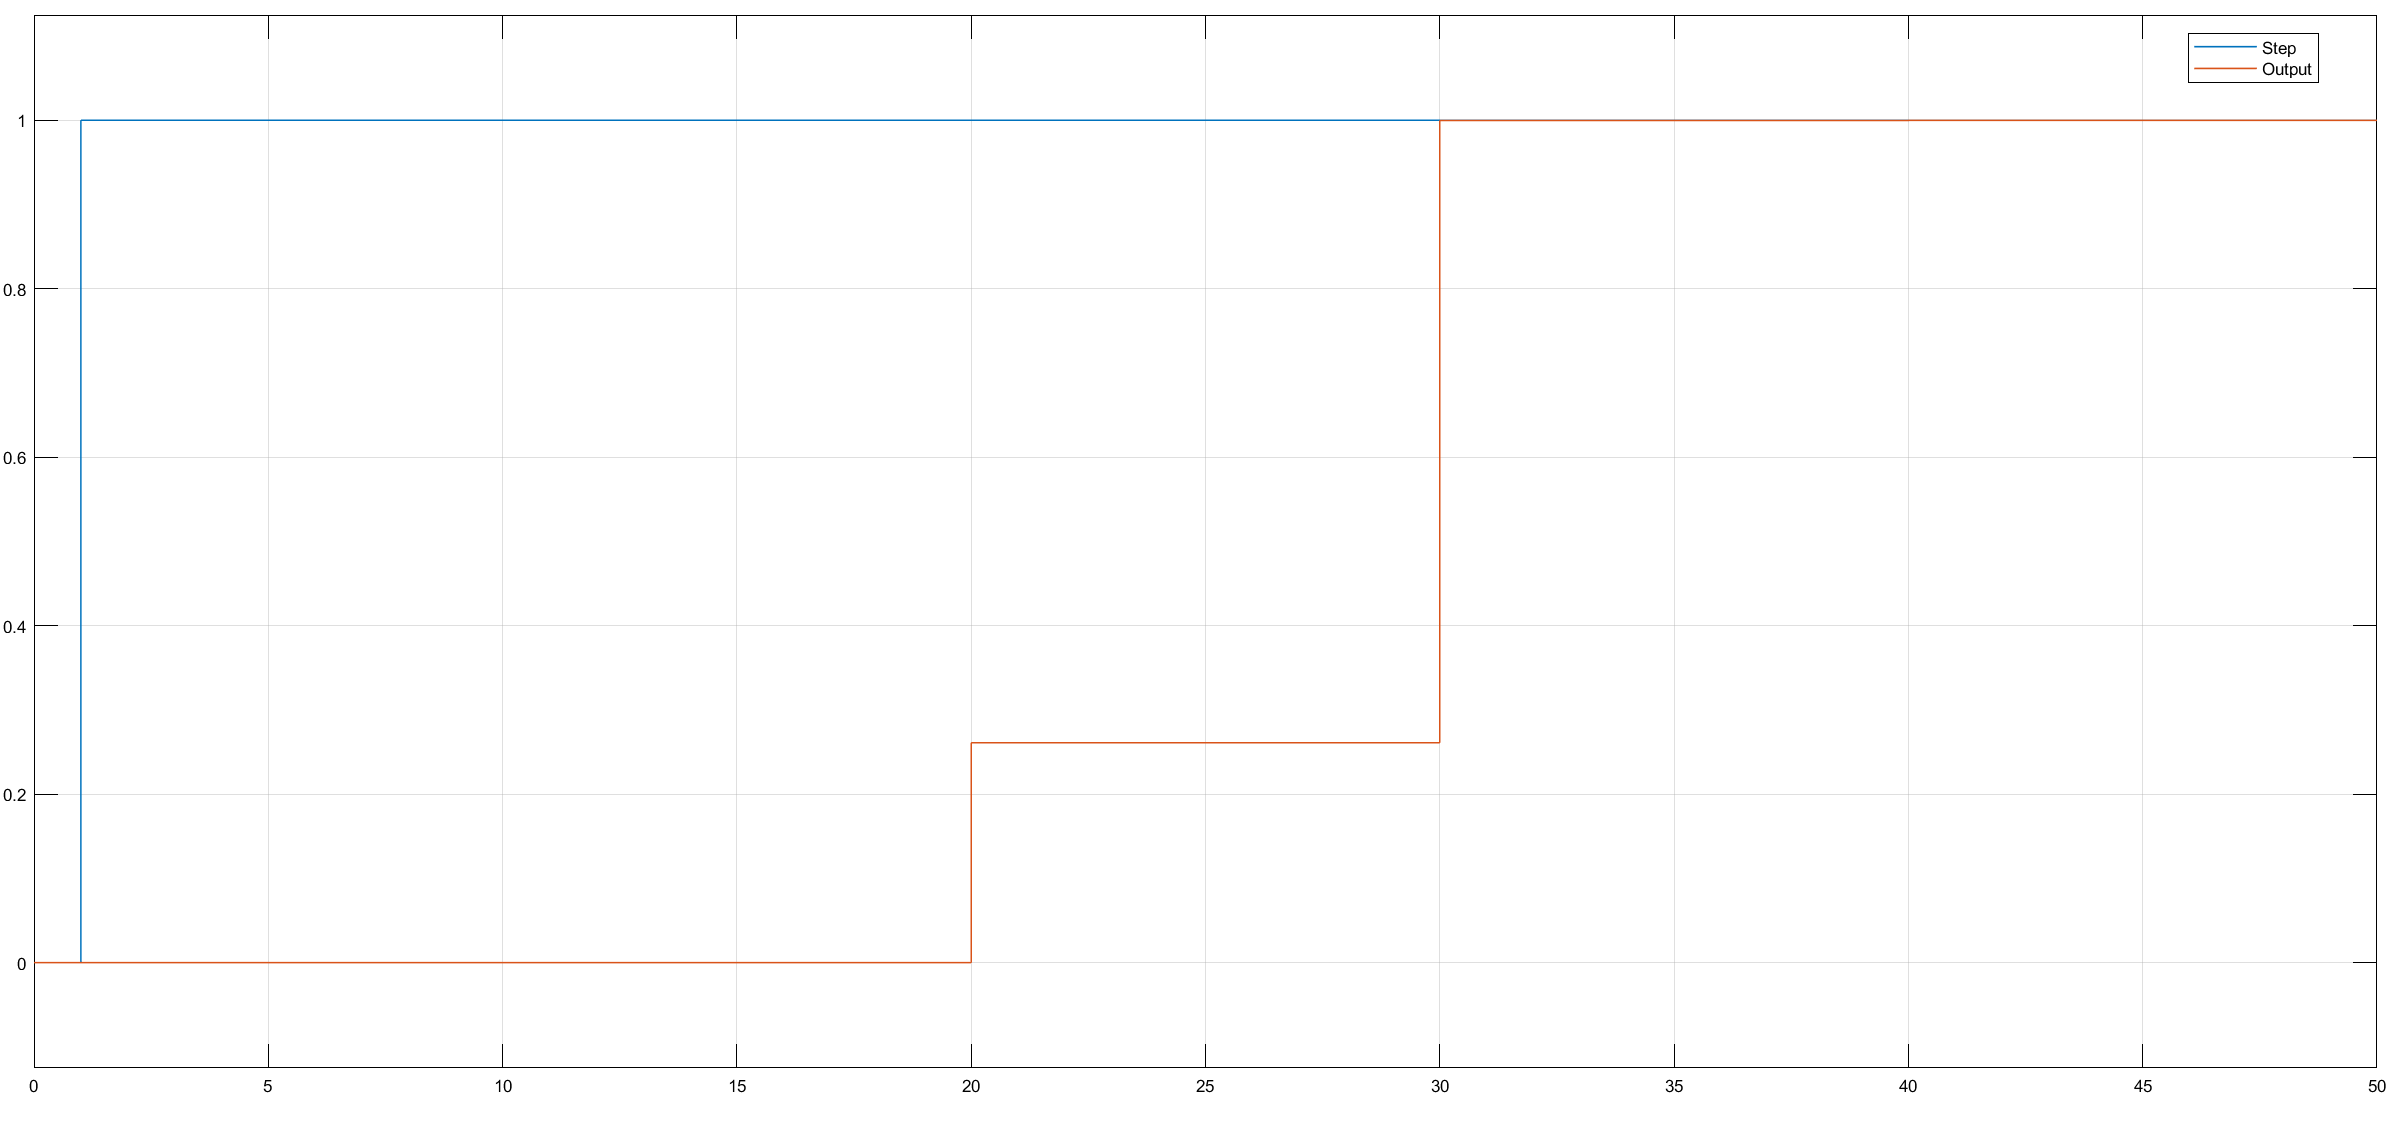

# **Comparing controllers (p8)**

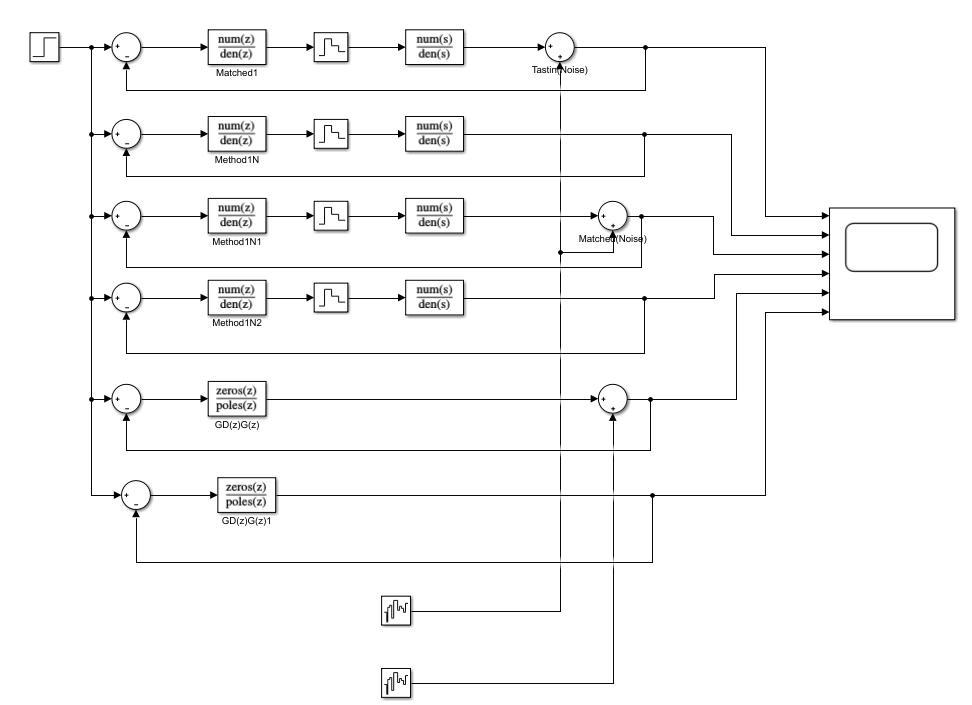

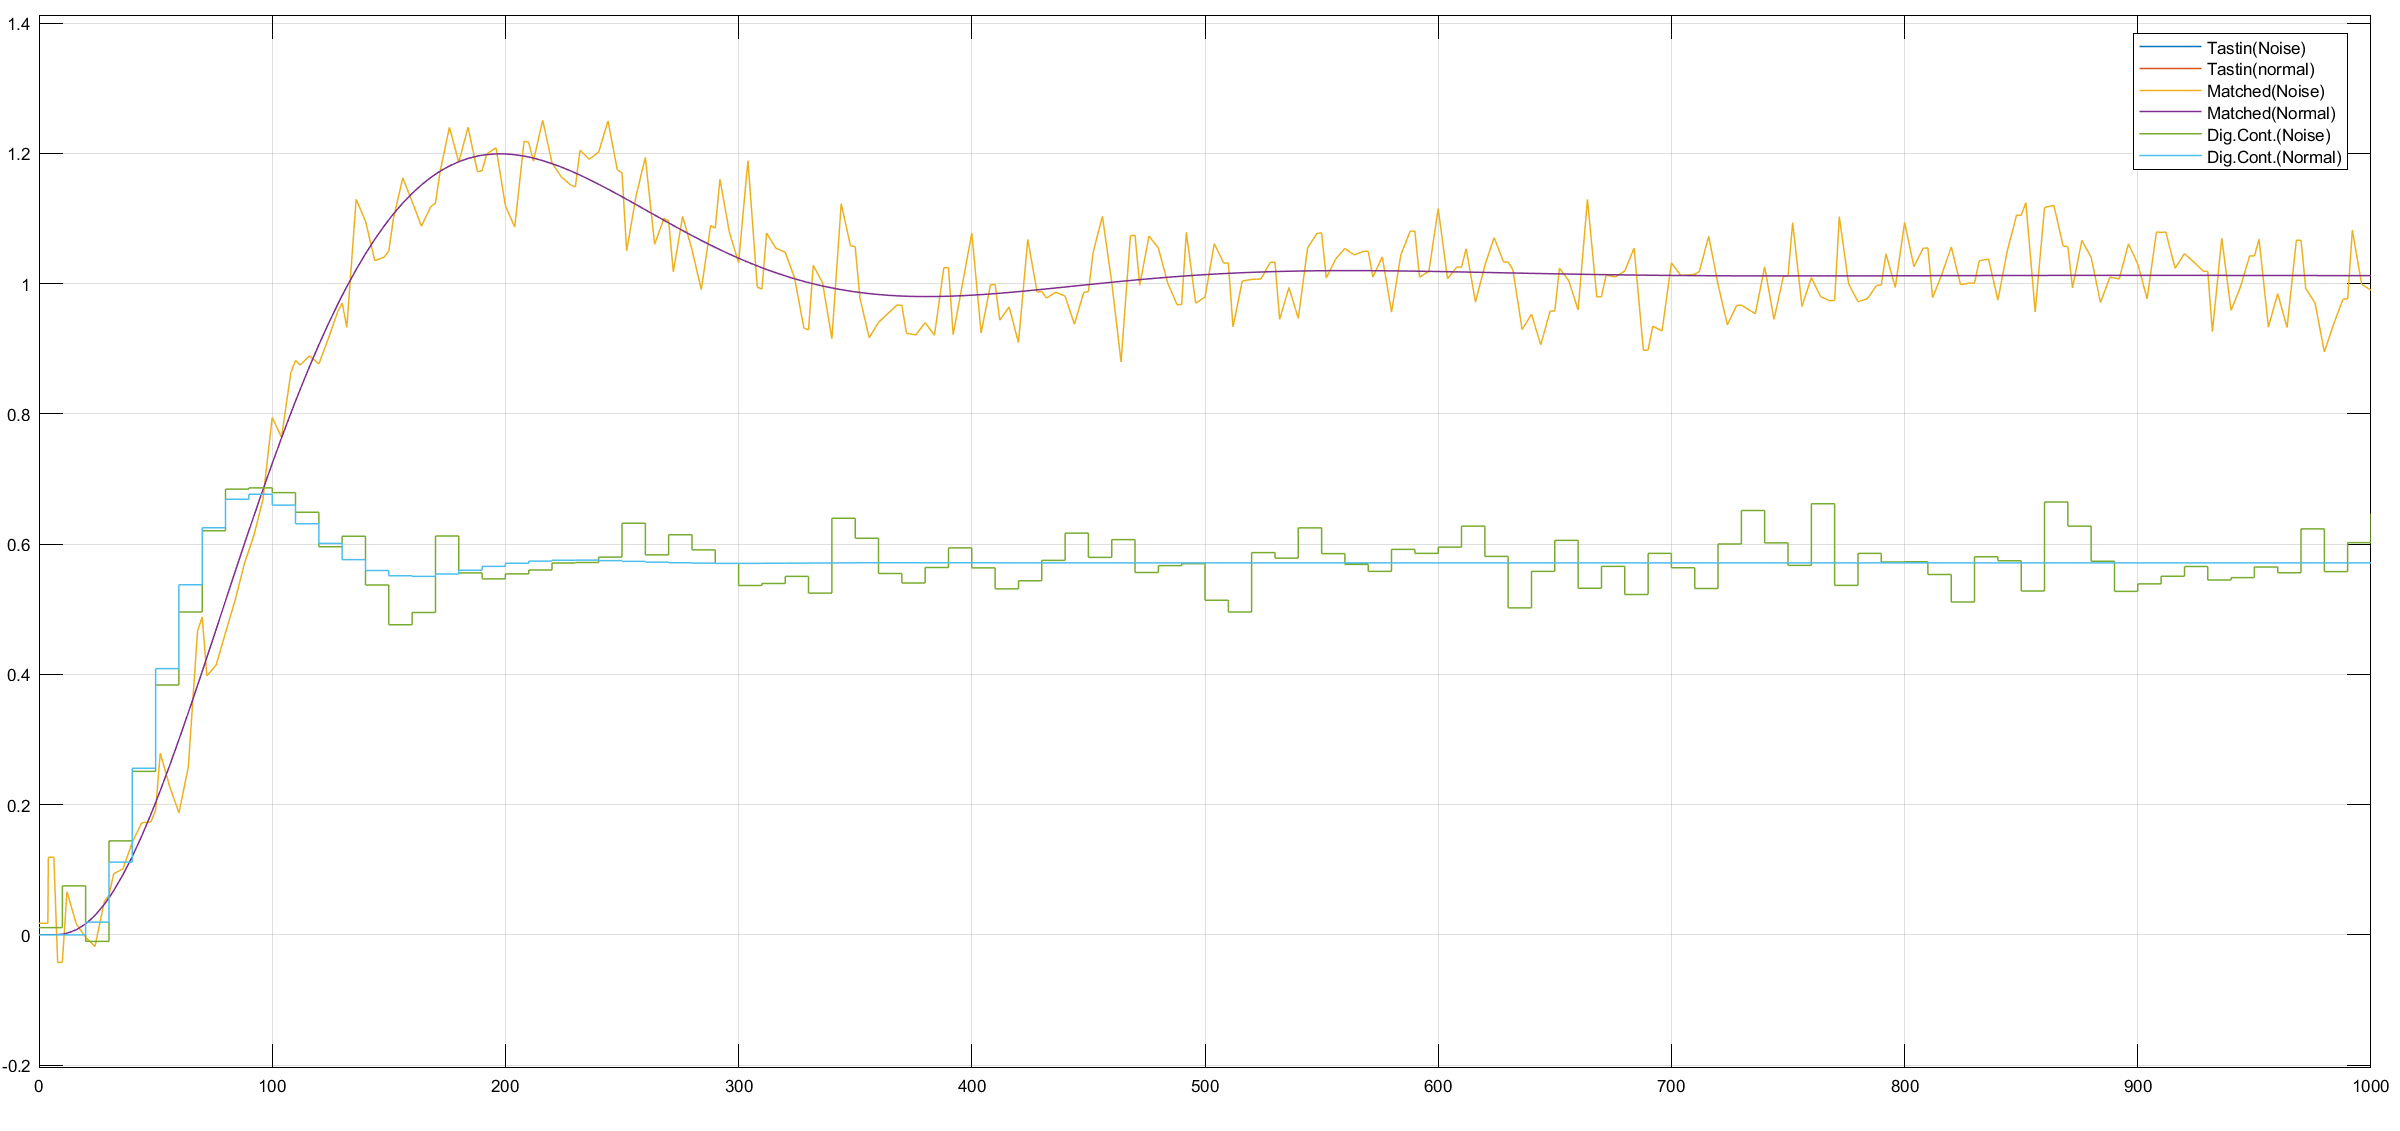

So The Digital Controller in part 5, Outperforms in comparsion with the Matched and Tastin Methods to resist with the white Noise.

*Tastin and Matched Methods Overlapped since the Digital controllers obtained for both of them are similar

(This is due to The fact that the Discretized version of the analog PD controller is the same for both case)

# **State space (p9)**

## Discrete State Space

Ts = 4;
sys = ss(A,B,C,D)

sys =
 
  A = 
             x1        x2        x3
   x1         0      -4.5         0
   x2         0    -0.025   1.3e-05
   x3         0         0  -0.09233
 
  B = 
            u1
   x1        0
   x2        0
   x3  0.08333
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



sys_d = c2d(sys,Ts)

sys_d =
 
  A = 
               x1          x2          x3
   x1           1      -17.13  -0.0004014
   x2           0      0.9048   4.125e-05
   x3           0           0      0.6912
 
  B = 
               u1
   x1  -4.635e-05
   x2   7.434e-06
   x3      0.2787
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Sample time: 4 seconds
Discrete-time state-space model.



G = sys_d.A; H = sys_d.B;

## Controllable & Observable

n = size(G,1);
M = [];
N = [];
for i = 0:n-1
    M = [M G^i*H];
    N = [N ; C*G^i];
end
M

M =    -0.0000   -0.0003   -0.0007
    0.0000    0.0000    0.0000
    0.2787    0.1926    0.1332


fprintf('Rank(M):%i\n',rank(M))

Rank(M):3


if rank(M) == n
    disp('(G,H) is controllable')
end

(G,H) is controllable


N

N =     1.0000         0         0
    1.0000  -17.1293   -0.0004
    1.0000  -32.6285   -0.0014


fprintf('Rank(N):%i\n',rank(N))

Rank(N):3


if rank(N) == n
    disp('(G,C) is observable')
end

(G,C) is observable


% Hankel Matrix
if rank(N*M) == n
    disp('State space is minimal')
end

State space is minimal


# **DeadBeat controller from the state space (p10)**

% we can use all of the states
tf_d = tf(sys_d)

tf_d =
 
  -4.635e-05 z^2 - 0.0001652 z - 3.666e-05
  ----------------------------------------
     z^3 - 2.596 z^2 + 2.221 z - 0.6254
 
Sample time: 4 seconds
Discrete-time transfer function.



[tf_Num,tf_Den] = tfdata(tf_d);
n = size(tf_Den{1},2);
a = zeros(1,n-1);
b = zeros(1,n);
for i = 1:n-1
    a(i) = tf_Den{1}(i+1);
    b(i) = tf_Num{1}(i);
end
W = [];
for i = 0:n-2
    W = [W ; flip(a(1:end-1-i)) 1 zeros(1,i)];
end
T = M*W;
K_deadbeat = -flip(a)*inv(T)

K_deadbeat = 	1.0e+05 *

   -0.0403    1.3010    0.0001


In order to achive the states, we need to implement the system with delay block:

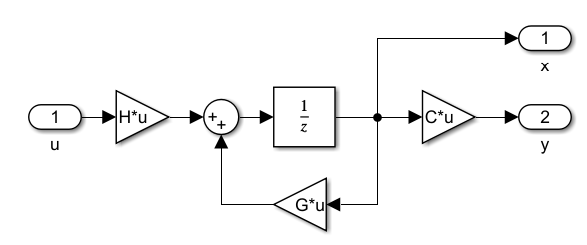

Then simply connect the state feedback controller:

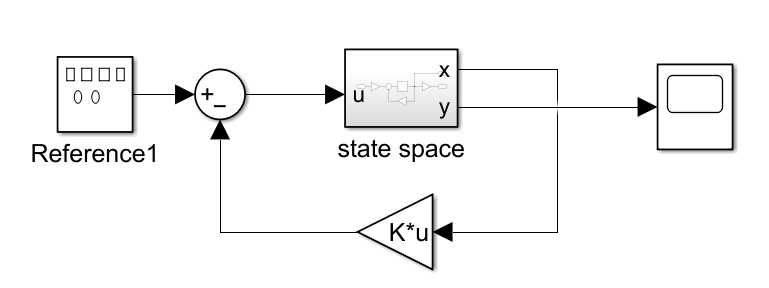

The other way is implement it as discrete state space block and connect the state feedback controller. But we need to set the C matrix equal to eye(3) because we need all the states in the output:

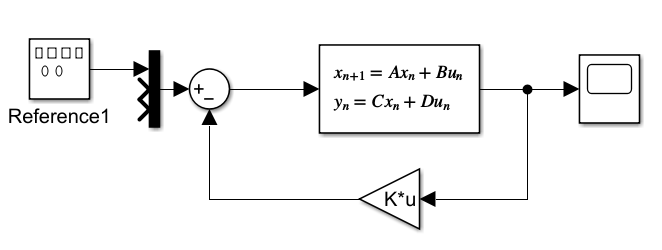

# **Deadbeat controller with full rank observer (p11)**

% x[k+1] = (G-LC)x[k] + Hu[k] + Ly[k]
G_new = transpose(G);
H_new = transpose(C);
L = transpose(acker(G_new,H_new,zeros(n-1,1)))

L =     2.5960
   -0.0997
 -531.9399


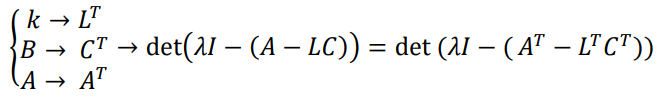

So the block of observer is something like this:

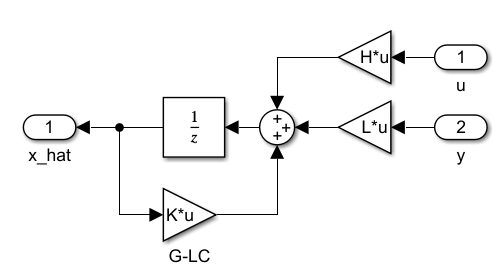

To compare states from system without observer and system with observer we impelement the circuit below.

The input is a sinous signal with the frequency of 0.005Hz.

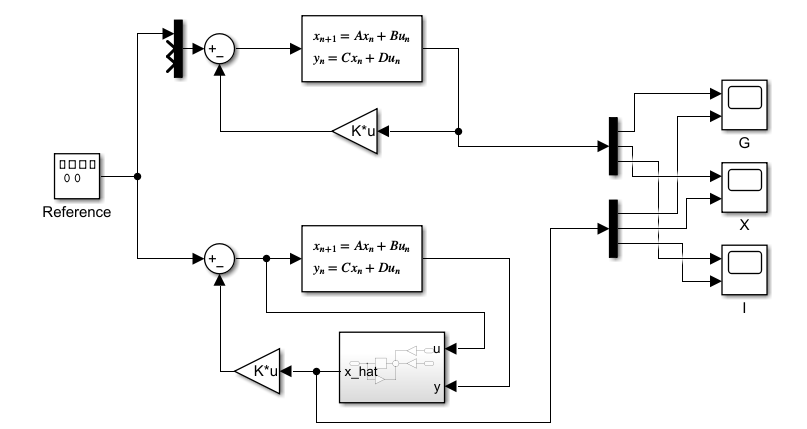

G:

    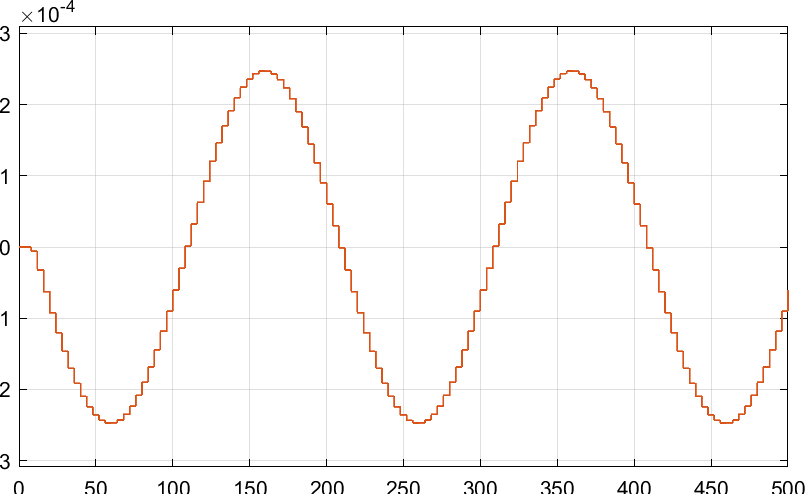

X:

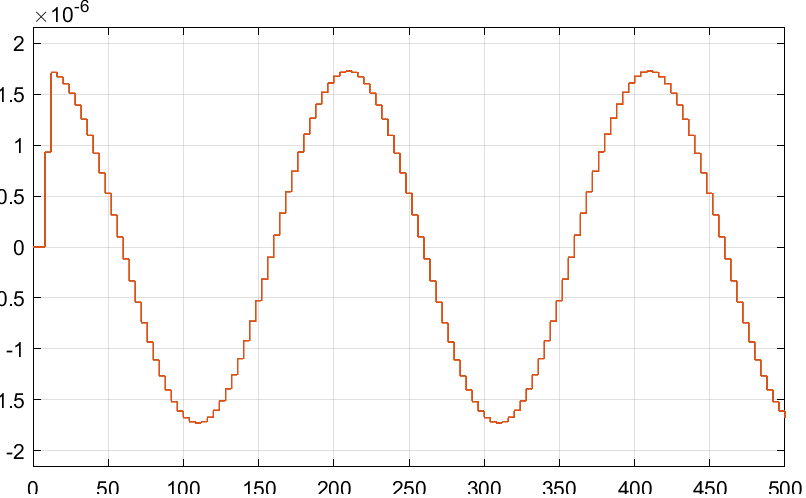

I:

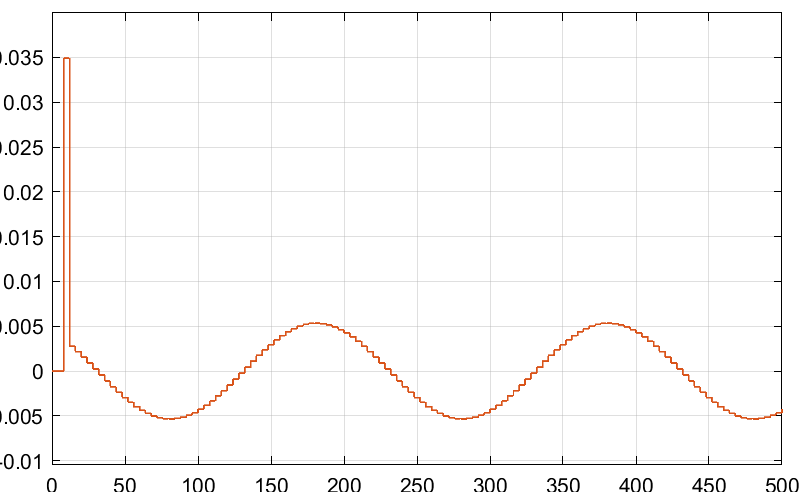

As we can see, observer prefectly follows the states. But if we apply the initial conditions, we can see the error between them that converges to zero over the time.

initial condition = 0.1

G: